close all;
clear;
clc

%prescribed parameters A,B, and C are calculated by the user input

indexIn = inputdlg ( ' Enter Index Number' , 'Index Number' )  ;
indexNo = str2double (indexIn{1}(1:end-1)); 
C = mod(indexNo , 10 ) ;
B = mod( floor(indexNo/10) ,10 ) ;
A = mod( floor(indexNo/100) ,10 ) ;

%parameters for the Bandpass filter

PassBandRippleMax=0.03+0.01*A;%Maximum passband ripple-:0.0900 dB
StopBandAttenuationMin=45+B;%Minimum stopband attenuation-:45 dB
LowerPassBand=C*100+300;%Lower passband edge-:1200 rad/s
UpperPassBand=C*100+700;%Upper passband edge-:1600 rad/s
LowerStopBand=C*100+150;%Lower stopband edge-:1050 rad/s
UpperStopBand=C*100+800;%Upper stopband edge-:1700 rad/s
SamplngFrequency=2*(C*100+1200);%Sampling frequency-:4200 rad/s

% Derived Specifications

TransitionBandWidth = min(LowerPassBand-LowerStopBand,UpperStopBand-UpperPassBand); %critical transition bandwidth
LowerCutOff = LowerPassBand-TransitionBandWidth/2; % lower cutoff frequency
UpperCutOff = UpperPassBand+TransitionBandWidth/2; % upper cutoff frequency
SamplingPeriod = 2*pi/SamplngFrequency; % sampling period

% Kaiser Window Parameters

deltaP = (10^(0.05*PassBandRippleMax) - 1)/ (10^(0.05*PassBandRippleMax) + 1); % calculating delta
deltaA = 10^(-0.05*StopBandAttenuationMin);
delta = min(deltaP,deltaA);

ActualStopBandAttenuation = -20*log10(delta);  % Actual stopband attenuation

if ActualStopBandAttenuation<=21               % Calculating alpha 
    alpha = 0;
elseif ActualStopBandAttenuation>21 && ActualStopBandAttenuation<= 50
    alpha = 0.5842*(ActualStopBandAttenuation-21)^0.4 + 0.07886*(ActualStopBandAttenuation-21);
else
    alpha = 0.1102*(ActualStopBandAttenuation-8.7);
end

if ActualStopBandAttenuation <= 21             % Calculating D
    D = 0.9222;
else
    D = (ActualStopBandAttenuation-7.95)/14.36;
end

N = ceil(SamplngFrequency*D/TransitionBandWidth +1); % order of the filter
if mod(N,2) == 0
    N = N+1;
end

n = -(N-1)/2:1:(N-1)/2;  % length of the filter
nCausal = 0 : 1: (N-1)/2;
beta = alpha*sqrt(1-(2*n/(N-1)).^2);

% Generating I(alpha) and I(beta)

syms k;
Ibeta = 1 + double(symsum(((1/factorial(k))*(beta/2).^k).^2, k, 1, Inf));
Ialpha = 1 + double(symsum(((1/factorial(k))*(alpha/2)^k)^2, k, 1, Inf));

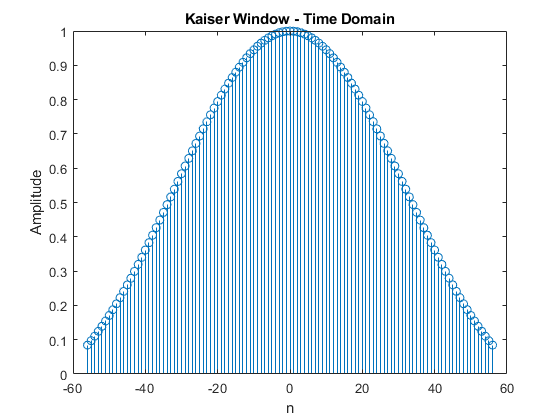

% Obtaining Kaiser Window 

KaiserWindow = Ibeta./Ialpha;
figure
stem(n,KaiserWindow)
xlabel('n')
ylabel('Amplitude')
title('Kaiser Window - Time Domain');

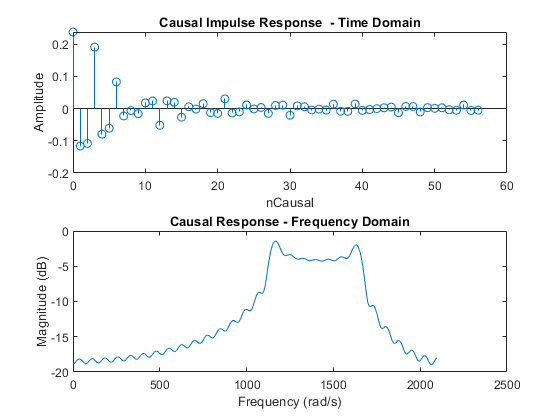

% Generating Impulse Response 

NNeg = -(N-1)/2:-1;
hNeg = 1./(NNeg*pi).*(sin(UpperCutOff*NNeg*SamplingPeriod)-sin(LowerCutOff*NNeg*SamplingPeriod));

NPosi = 1:(N-1)/2;
hPosi = 1./(NPosi*pi).*(sin(UpperCutOff*NPosi*SamplingPeriod)-sin(LowerCutOff*NPosi*SamplingPeriod));

hZero = 2/SamplngFrequency*(UpperCutOff-LowerCutOff);

hTotal = [hNeg,hZero,hPosi];
figure
subplot(2,1,1)
stem(nCausal,[hZero,hPosi])
xlabel('nCausal')
ylabel('Amplitude')
title(strcat('Causal Impulse Response  - Time Domain'));

subplot(2,1,2)
[hi_f,wi_f] = freqz([hZero,hPosi]);
wi_f = wi_f/SamplingPeriod;
hi_f = 20*log10(abs(hi_f));
plot(wi_f,hi_f)
xlabel('Frequency (rad/s)')
ylabel('Magnitude (dB)')
title(strcat('Causal Response - Frequency Domain'));

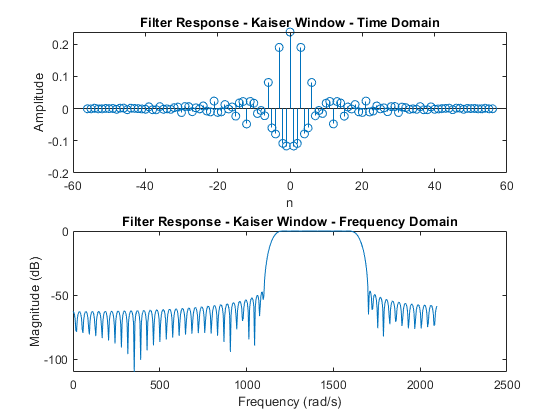

% Applying the window to the filter


BandPassFilter = hTotal.*KaiserWindow;
figure
subplot(2,1,1)
stem(n,BandPassFilter)
xlabel('n')
ylabel('Amplitude')
title(strcat('Filter Response - Kaiser Window - Time Domain'));

subplot(2,1,2)
[h,w] = freqz(BandPassFilter);
w = w/SamplingPeriod;
h = 20*log10(abs(h));
plot(w,h)
xlabel('Frequency (rad/s)')
ylabel('Magnitude (dB)')
title(strcat('Filter Response - Kaiser Window - Frequency Domain'));

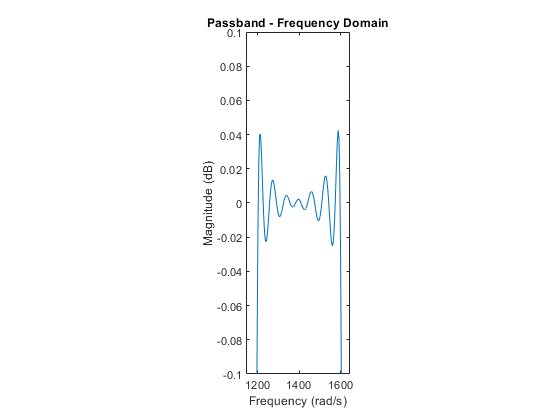

% Plotting the Passband %%

figure
subplot(1,3,2)
start = round(length(w)/(SamplngFrequency/2)*LowerCutOff);
finish = round((length(w)/(SamplngFrequency/2)*UpperCutOff));
wpass = w(start:finish);
hpass = (h(start:finish));
plot(wpass,hpass)
axis([-inf, inf, -0.1, 0.1]);
xlabel('Frequency (rad/s)')
ylabel('Magnitude (dB)')
title('Passband - Frequency Domain');

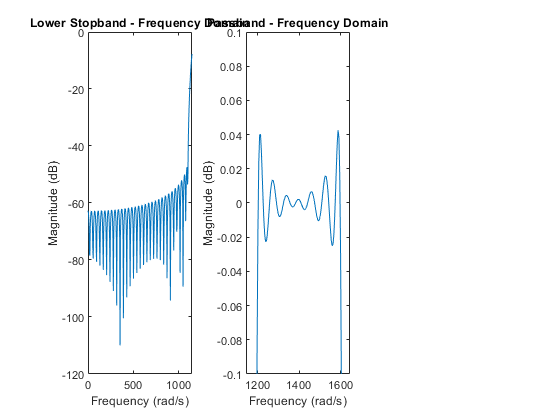

% Plotting the Lower Stopband

subplot(1,3,1)
Start_Low = 1;
Finish_Low = round(length(w)/(SamplngFrequency/2)*LowerCutOff);
wlower= w(Start_Low:Finish_Low);
hlower = (h(Start_Low:Finish_Low));
plot(wlower,hlower)
axis([-inf, inf, -120, 0]);
xlabel('Frequency (rad/s)')
ylabel('Magnitude (dB)')
title('Lower Stopband - Frequency Domain');

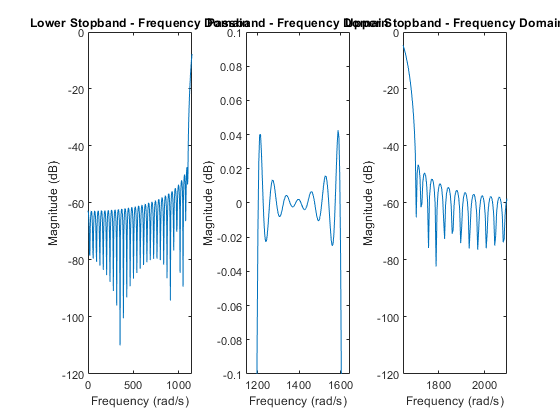

% Plotting the Upper Stopband

subplot(1,3,3)
Start_Upper = round((length(w)/(SamplngFrequency/2)*UpperCutOff));
wupper= w(Start_Upper:end);
hupper = (h(Start_Upper:end));
plot(wupper,hupper)
axis([-inf, inf, -120, 0]);
xlabel('Frequency (rad/s)')
ylabel('Magnitude (dB)')
title('Upper Stopband - Frequency Domain');

% Input signal generation 

Omega1 = LowerCutOff/2;                    % component frequencies of the input
Omega2 = LowerCutOff + (UpperCutOff-LowerCutOff)/2;
Omega3 = UpperCutOff + (SamplngFrequency/2-UpperCutOff)/2;
OmegaIn = [Omega1,Omega2,Omega3];

n1 = 0:1:300;                  %% x axis for discrete signal
n2 = 0:0.1:300;                %% x axis for envelope

xnt = 0;     
xdash =0;

for each = OmegaIn                        
    xnt = xnt+ sin(each.*n1.*SamplingPeriod);     %% generate discrete signal
    xdash = xdash+sin(each.*n2.*SamplingPeriod);  %% generate envelope
end

% Using DFT to check the filtering 

Npoint = length(xnt) + length(BandPassFilter) - 1;  % length for fft in x dimension
xfft = fft(xnt,Npoint);
filterfft = fft(BandPassFilter,Npoint);
outfft = filterfft .* xfft;
out = ifft(outfft,Npoint);

out1 = out(floor(N/2)+1:length(out)-floor(N/2)); % account for shifting delay

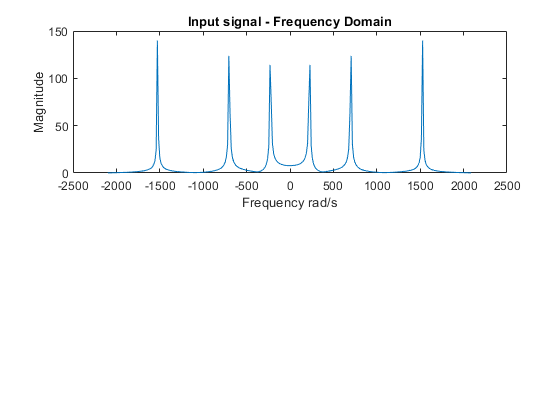

% Frequency domain representation of input signal before filtering

figure 
subplot(2,1,1)

Npoint = length(xnt);  
xfft = fft(xnt,Npoint);
x1 = n1/length(n1)*SamplngFrequency-SamplngFrequency/2;
plot(x1,abs(xfft))
xlabel('Frequency rad/s')
ylabel('Magnitude')
title(strcat('Input signal - Frequency Domain'));

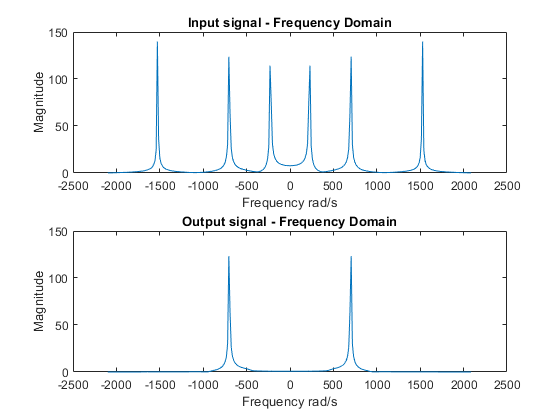

% Frequency domain representation of input signal after filtering

subplot(2,1,2)
Npoint = length(out1);  % length for fft in x dimension
xffout = fft(out1,Npoint);
x1 = n1/length(n1)*SamplngFrequency-SamplngFrequency/2;
plot(x1,abs(xffout))
xlabel('Frequency rad/s')
ylabel('Magnitude')
title(strcat('Output signal - Frequency Domain'));

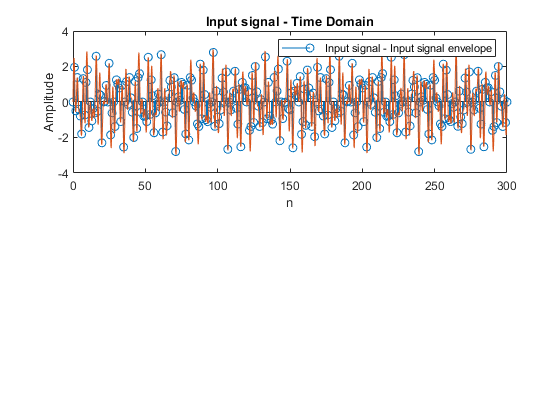

% time domain representation of input signal before filtering

figure
subplot(2,1,1)
stem(n1,xnt)
xlabel('n')
ylabel('Amplitude')
title(strcat('Input signal - Time Domain'));
hold on 
plot(n2,xdash)
legend('Input signal - Input signal envelope');

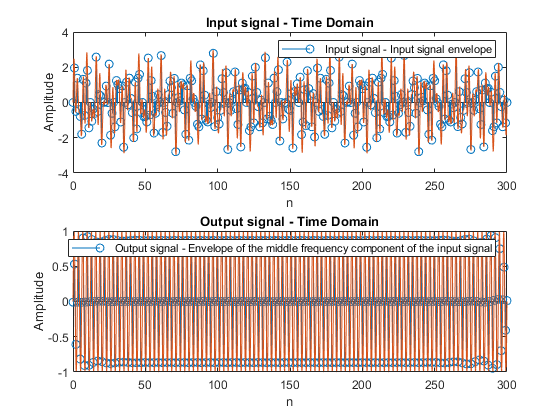

% Time domain representation of input signal after filtering

subplot(2,1,2)
stem(n1,out1)
xlabel('n')
ylabel('Amplitude')
title(strcat('Output signal - Time Domain'));

hold on
plot(n2,sin(Omega2.*n2.*SamplingPeriod))
legend('Output signal - Envelope of the middle frequency component of the input signal');